clear 
clc

V0 = 0.895;                     % input swing
C1 = 38.72E-12;                 % load cap
Fs = 10E6;                     % sample rate
wt = [101, 249, 499] / 1024;     
Fin = wt .* Fs;                 % input frequency (Hz)
Ron0 = 6.5;                     % On-Resistance (ohm)
L = [0.2, 0.4, 0.6,0.8, 1, 2, 3];
alpha = [-1.15, -0.15, 0.15, 0.3, 0.4, 0.6, 0.68];
VTH = 0.48;

getHD_new(Ron0*(1.8-VTH)/(db2mag(-1.1)-VTH), V0, C1, Fin(3), alpha(1))

ans =   -78.3175  -80.4067


%SD Exchange effect


Cb = 10;
Cp1 = 1;
Cp2 = 1;
Cp3 = 1;

Ctot = Cb + Cp1 + Cp2 + Cp3;
% Vgs0 = [Cb * 1.8 - (Cp1 + Cp2)*0.9 - Cp3 * 0.18] / Ctot
Vgs1 = V0* Cp1/Ctot;
mag2db(Vgs1)

ans = -23.2424

Vgs0 = (Cb * 1.8 - (Cp1 + Cp2)*0.9 - Cp3 * 0.18) / Ctot

Vgs0 = 1.2323

mag2db(Vgs0)

ans = 1.8144

% Vgs0 = db2mag(0.71)
Ron = Ron0*(1.8-VTH)/(Vgs0-VTH)

Ron = 11.4049

% Ron = db2mag(7.5)
mag2db(Ron)

ans = 21.1418

R2 = ((Vgs1 / (Vgs0-VTH))^2)* Ron / 2

R2 = 0.0478

mag2db(R2)

ans = -26.4194

mag2db(R2*C1*Fin(3)*pi*V0)

ans = -91.9252

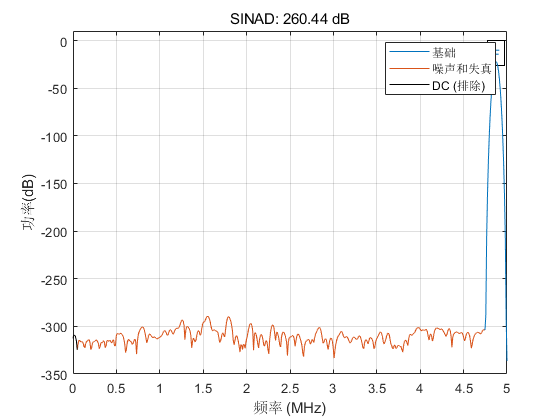

ans = 260.4419

t = 0:1/Fs:1/Fs*1023;
omega = 2*pi*Fin(3);
Vgs = Vgs0 + Vgs1*sin(omega*t);
sinad(Vgs, Fs)

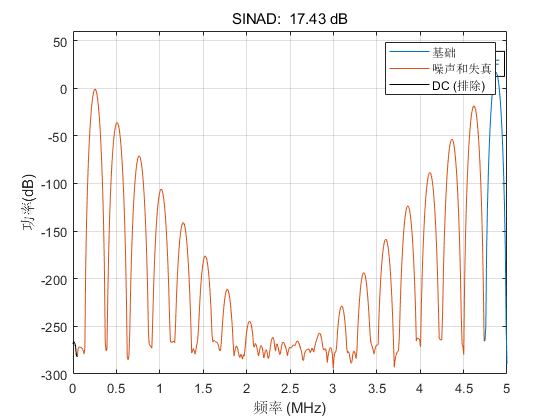

ans = 17.4343

ron = 1./(Vgs - 0.45) / (280E-6 * 16*3/0.2);
sinad(ron,Fs)

[~, harmpower, harmfreq]= thd(ron,Fs, 5, 'aliased')

harmpower =    16.6403
   -0.8717
  -18.3836
  -35.8956
  -53.4076


harmfreq = 	1.0e+06 *

    4.8730
    0.2539
    4.6191
    0.5078
    4.3652


harmpower(2) - harmpower(1)

ans = -17.5120

harmpower(3) - harmpower(1)

ans = -35.0240